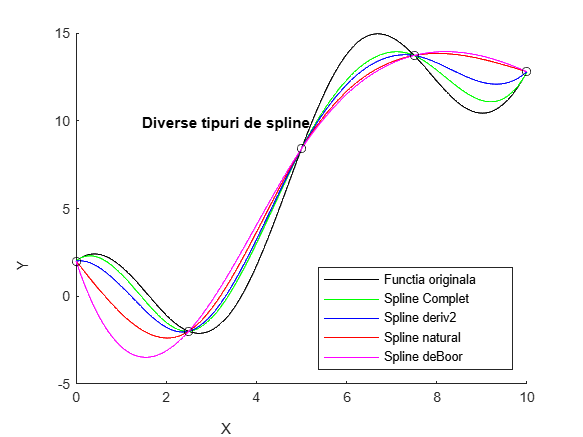

close all

f = @(x) 5*cos(x) + 2 * x - 3;
fd = @(x) -5*sin(x) + 2;
fdd = @(x) -5*cos(x);

% Noduri și valori
x = linspace(0, 10, 5);
y = f(x);

% Puncte de evaluare
n = max(x);
tg = linspace(0, n, 1000);

%% Plot funcția originală
figure;
hold on;
p1 = plot(tg, f(tg), 'k');

%% Tip 0 - Spline Complet
c = CubicSplinec(x, y, 0, [fd(0), fd(10)]);
values = evalsplinec(x, c, tg);
p2 = plot(tg, values, 'g');

%% Tip 1 - Spline cu derivata a doua dată
c = CubicSplinec(x, y, 1, [fdd(0), fdd(10)]);
values = evalsplinec(x, c, tg);
p3 = plot(tg, values, 'b');

%% Tip 2 - Spline natural
c = CubicSplinec(x, y, 2);
values = evalsplinec(x, c, tg);
p4 = plot(tg, values, 'r');

%% Tip 3 - Spline de Boor (not-a-knot)
c = CubicSplinec(x, y, 3);
values = evalsplinec(x, c, tg);
p5 = plot(tg, values, 'm');

% Noduri inițiale
plot(x, y, 'ko');

%% Finalizare
hold off;
legend([p1,p2,p3,p4,p5], 'Functia originala', 'Spline Complet', 'Spline deriv2', 'Spline natural', 'Spline deBoor', 'Location', 'southeast');
xlabel('X');
ylabel('Y');
title('Diverse tipuri de spline');


%% Funcții locale

function c = CubicSplinec(x, f, type, der)
    if (nargin<4) || (type==2), der = [0, 0]; end

    n = length(x);
    if any(diff(x) < 0), [x, ind] = sort(x); else ind = 1:n; end
    y = f(ind); x = x(:); y = y(:);

    dx = diff(x);
    ddiv = diff(y)./dx;
    ds = dx(1:end-1); dd = dx(2:end);
    dp = 2*(ds + dd);
    md = 3*(dd .* ddiv(1:end-1) + ds .* ddiv(2:end));

    switch type
        case 0 % complet
            dp1 = 1; dpn = 1; vd1 = 0; vdn = 0;
            md1 = der(1); mdn = der(2);
        case {1,2} % derivata a 2a sau natural
            dp1 = 2; dpn = 2; vd1 = 1; vdn = 1;
            md1 = 3*ddiv(1) - 0.5*dx(1)*der(1);
            mdn = 3*ddiv(end) + 0.5*dx(end)*der(2);
        case 3 % deBoor
            x31 = x(3) - x(1); xn = x(n) - x(n-2);
            dp1 = dx(2); dpn = dx(end-1);
            vd1 = x31; vdn = xn;
            md1 = ((dx(1)+2*x31)*dx(2)*ddiv(1) + dx(1)^2*ddiv(2))/x31;
            mdn = (dx(end)^2*ddiv(end-1) + (2*xn+dx(end))*dx(end-1)*ddiv(end))/xn;
    end

    dp = [dp1; dp; dpn];
    dp1 = [0; vd1; dd];
    dm1 = [ds; vdn; 0];
    md = [md1; md; mdn];

    A = spdiags([dm1, dp, dp1], -1:1, n, n);
    m = A \ md;

    c(:,4) = y(1:end-1);
    c(:,3) = m(1:end-1);
    c(:,1) = (m(2:end) + m(1:end-1) - 2*ddiv)./(dx.^2);
    c(:,2) = (ddiv - m(1:end-1))./dx - dx.*c(:,1);
end

function z = evalsplinec(x, c, t)
    n = length(x);
    x = x(:); t = t(:);
    k = ones(size(t));
    for j = 2:n-1
        k(x(j) <= t) = j;
    end
    s = t - x(k);
    z = c(k,4) + s.*(c(k,3) + s.*(c(k,2) + s.*c(k,1)));
end
